## Define the Fuzzy Logic Controller

Create an empty fuzzy logic controller without adding any rules.

controller = mamfis(   ... 
    'NumInputs', 4,    ...
    'NumInputMFs', 2,  ...
    'NumOutputs', 1,   ...
    'NumOutputMFs', 6, ... 
    'AddRule', 'none'  ...
);

Define the inputs (angle, angular velocity, position, and velocity) and their membership functions

 % Maximum occurs when the cart is lying flat on the floor
max_angle = pi/2; % In Rad

controller.Inputs(1).Name = 'CART_ANGLE'; 
controller.Inputs(1).Range = [-max_angle max_angle];
controller.Inputs(1).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(1).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(1).MembershipFunctions(1).Parameters = [-max_angle/2 max_angle/2]; 
controller.Inputs(1).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(1).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(1).MembershipFunctions(2).Parameters = [-max_angle/2 max_angle/2]; 

% Maximum found by running the simulation in open loop mode and observing the peak
max_angular_velocity = 10; % In Rad/s

controller.Inputs(2).Name = 'CART_ANGULAR_VELOCITY'; 
controller.Inputs(2).Range = [-max_angular_velocity max_angular_velocity];
controller.Inputs(2).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(2).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(2).MembershipFunctions(1).Parameters = [-max_angular_velocity/2 max_angular_velocity/2]; 
controller.Inputs(2).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(2).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(2).MembershipFunctions(2).Parameters = [-max_angular_velocity/2 max_angular_velocity/2]; 

% Maximum taken as the size of the floor 
max_position = 1; % In m

controller.Inputs(3).Name = 'CART_POSITION'; 
controller.Inputs(3).Range = [-max_position max_position]; 
controller.Inputs(3).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(3).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(3).MembershipFunctions(1).Parameters = [-max_position/2 max_position/2]; 
controller.Inputs(3).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(3).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(3).MembershipFunctions(2).Parameters = [-max_position/2 max_position/2]; 


% Maximum velocity is unknown
max_velocity = 10; % In m/s

controller.Inputs(4).Name = 'CART_VELOCITY'; 
controller.Inputs(4).Range = [-max_velocity max_velocity]; 
controller.Inputs(4).MembershipFunctions(1).Name = 'NEGATIVE'; 
controller.Inputs(4).MembershipFunctions(1).Type = 'zmf'; 
controller.Inputs(4).MembershipFunctions(1).Parameters = [-max_velocity/2 max_velocity/2]; 
controller.Inputs(4).MembershipFunctions(2).Name = 'POSITIVE'; 
controller.Inputs(4).MembershipFunctions(2).Type = 'smf'; 
controller.Inputs(4).MembershipFunctions(2).Parameters = [-max_velocity/2 max_velocity/2];

Visualize the input membership functions

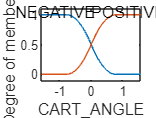

plotmf(controller, 'input', 1, 1000);

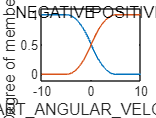

plotmf(controller, 'input', 2, 1000);

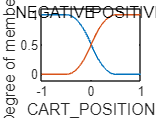

plotmf(controller, 'input', 3, 1000);

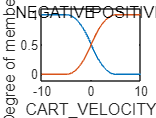

plotmf(controller, 'input', 4, 1000);

Define the outputs and their membership functions

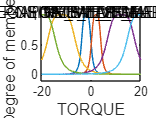

% Maximum torque is unknown
max_torque = 20; % In Nm

controller.Outputs(1).Name = 'TORQUE';
controller.Outputs(1).Range = [-max_torque, max_torque];

controller.Outputs(1).MembershipFunctions(1).Name = 'NEGATIVE_SMALL';
controller.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; 
controller.Outputs(1).MembershipFunctions(1).Parameters = [0.1*max_torque, 2, -0.1*max_torque]; 
controller.Outputs(1).MembershipFunctions(2).Name = 'POSITIVE_SMALL';
controller.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; 
controller.Outputs(1).membershipFunctions(2).Parameters = [0.1*max_torque, 2, 0.1*max_torque];

controller.Outputs(1).MembershipFunctions(3).Name = 'NEGATIVE_MEDIUM';
controller.Outputs(1).MembershipFunctions(3).Type = 'gbellmf'; 
controller.Outputs(1).MembershipFunctions(3).Parameters = [0.3*max_torque, 2, -0.6*max_torque]; 
controller.Outputs(1).MembershipFunctions(4).Name = 'POSITIVE_MEDIUM';
controller.Outputs(1).MembershipFunctions(4).Type = 'gbellmf'; 
controller.Outputs(1).membershipFunctions(4).Parameters = [0.3*max_torque, 2, 0.6*max_torque]; 

controller.Outputs(1).MembershipFunctions(5).Name = 'NEGATIVE_LARGE';
controller.Outputs(1).MembershipFunctions(5).Type = 'gbellmf'; 
controller.Outputs(1).MembershipFunctions(5).Parameters = [0.3*max_torque, 2, -max_torque]; 
controller.Outputs(1).MembershipFunctions(6).Name = 'POSITIVE_LARGE';
controller.Outputs(1).MembershipFunctions(6).Type = 'gbellmf'; 
controller.Outputs(1).membershipFunctions(6).Parameters = [0.3*max_torque, 2, max_torque]; 

plotmf(controller, 'output', 1, 1000);

Define the rules. As reference, take positive X to the right, and positive Z sticking out of the page.

- Consider a positive angle as tipping in the positive x direction

- Consider a positive position as being farther in the positive x direction

- Consider a positive torque as a torque that will move the cart in the positive x direction

rules = [ ...
    "If CART_ANGLE is NEGATIVE then TORQUE is NEGATIVE_MEDIUM";           ...
    "If CART_ANGLE is POSITIVE then TORQUE is POSITIVE_MEDIUM";           ...
    "If CART_ANGULAR_VELOCITY is NEGATIVE then TORQUE is NEGATIVE_LARGE"; ...
    "If CART_ANGULAR_VELOCITY is POSITIVE then TORQUE is POSITIVE_LARGE"; ...
    "If CART_POSITION is NEGATIVE then TORQUE is POSITIVE_SMALL";         ...
    "If CART_POSITION is POSITIVE then TORQUE is NEGATIVE_SMALL";         ...
    "If CART_VELOCITY is NEGATIVE then TORQUE is NEGATIVE_MEDIUM";        ...
    "If CART_VELOCITY is POSITIVE then TORQUE is POSITIVE_MEDIUM";        ...
];
controller = addRule(controller, rules);

## Simulate

Generate a comparison video of the robots ability to balance under partial control for each fuzzy logic input.

% tests = {
%   ["none"],                                           ... % Mode 1
%   ["angle"],                                          ... % Mode 2
%   ["angle","angular_velocity"],                       ... % Mode 3
%   ["angle","angular_velocity","position"],            ... % Mode 4
%   ["angle","angular_velocity","position","velocity"], ... % Mode 5
% };
%
% open_system("model")
% for index = 1:length(tests)
%     input = Simulink.SimulationInput("model");
%     input = removeDisturbanceForce(input);
%     input = removeDisturbanceAngle(input);
%     input = setTargetPosition(input,0.5,20);
%     input = input.setModelParameter('StopTime','40');
%     if sum(contains(tests{index}, "angle")) == 0
%         input = input.setBlockParameter('model/angle_en','Gain','0');
%     end
%     if sum(contains(tests{index}, "angular_velocity")) == 0
%         input = input.setBlockParameter('model/angular_velocity_en','Gain','0');
%     end
%     if sum(contains(tests{index}, "position")) == 0
%         input = input.setBlockParameter('model/position_en','Gain','0');
%     end
%     if sum(contains(tests{index}, "velocity")) == 0
%         input = input.setBlockParameter('model/velocity_en','Gain','0');
%     end
%     result = sim(input);
%     smwritevideo("model","results/mode" + int2str(index),"VideoFormat","mpeg-4","FrameSize",[400,400],'tile',4);
% end 
%
% generateComparisonVideo("mode",length(tests),"modeComparison");

Generate a comparison video of the robots ability to deal with increasing slope.

% angles = -4:2:4
% open_system("model")
% for index = 1:length(angles)
%     input = Simulink.SimulationInput("model");
%     input = input.setModelParameter('StopTime','20');
%     input = removeDisturbanceForce(input);
%     input = setDisturbanceAngle(input,angles(index));
%     result = sim(input);
%     smwritevideo("model","results/angle" + int2str(index),"VideoFormat","mpeg-4","FrameSize",[400,400],'tile',1);
% end

%generateComparisonVideo("angle",length(angles),"angleComparison");

Generate a comparison video of the robots ability to drive up and downhill.

% positions = [-0.5,0,0.5]
% open_system("model")
% for index = 1:length(positions)
%     input = Simulink.SimulationInput("model");
%     input = input.setModelParameter('StopTime','10');
%     input = removeDisturbanceForce(input);
%     input = setDisturbanceAngle(input,-2);
%     input = setTargetPosition(input,positions(index),1000);
%     result = sim(input);
%     smwritevideo("model","results/slope" + int2str(index),"VideoFormat","mpeg-4","FrameSize",[400,400],'tile',1);
% end

%generateComparisonVideo("angle",length(angles),"angleComparison");

Generate a comparison video of the robots ability to deal with disturbance force.

% open_system("model")
% forces = 0:2:10;
% %forces = [8,10];
% for index = 1:length(forces)
%     input = Simulink.SimulationInput("model");
%     input = input.setModelParameter('StopTime','10');
%     input = setDisturbanceForce(input,forces(index));
%     input = removeDisturbanceAngle(input);
%     input = removeTargetPosition(input);
%     result = sim(input);
%     smwritevideo("model","results/force" + int2str(index),"VideoFormat","mpeg-4","FrameSize",[1600,400],'tile',1);
% end

%generateComparisonVideo("force",length(forces),"forceComparison");

Generate a plot of maximum displacement due to disturbance force.

% open_system("model")
% forces = 0:5;
% max_position = {};
% for index = 1:length(forces)
%     input = Simulink.SimulationInput("model");
%     input = input.setModelParameter('StopTime','5');
%     input = setDisturbanceForce(input,forces(index));
%     input = removeDisturbanceAngle(input);
%     input = removeTargetPosition(input);
%     result = sim(input);
%     max_position{index} = max(abs(result.position.Data));
% end
% plot(forces,cell2mat(max_position));
% xlabel("Disturbance Force (N)");
% ylabel("Maximum Displacement (m)");

## Utilities

function generateComparisonVideo(sourcePath,sourceCount,destinationPath)
    outputVideo = VideoWriter("results/" + destinationPath,'MPEG-4');
    outputVideo.FrameRate = 30;
    open(outputVideo);
    inputVideos = {};
    for index = 1:sourceCount
        inputVideos{index} = VideoReader("results/" + sourcePath + int2str(index) + ".mp4");
    end
    for num = 1:inputVideos{1}.NumFrames
        img = {};
        for index = 1:length(inputVideos)
            img{index} = readFrame(inputVideos{index});
        end
        imgt = horzcat(cell2mat(img));
        writeVideo(outputVideo, imgt);
    end
    close(outputVideo);
end

function newSimInput = setDisturbanceAngle(simInput,angle)
    newSimInput = simInput.setBlockParameter('model/disturbance_angle','Value',int2str(angle));
end
function newSimInput = removeDisturbanceAngle(simInput)
    newSimInput = simInput.setBlockParameter('model/disturbance_angle','Value','0');
end

function newSimInput = setDisturbanceForce(simInput,amplitude)
    simInput = simInput.setBlockParameter('model/disturbance_force','Amplitude',int2str(amplitude));
    simInput = simInput.setBlockParameter('model/disturbance_force','Period','10');
    newSimInput = simInput.setBlockParameter('model/disturbance_force','PulseWidth','5'); % 1/4 second
end
function newSimInput = removeDisturbanceForce(simInput)
    newSimInput = simInput.setBlockParameter('model/disturbance_force','Amplitude','0');
end

function newSimInput = setTargetPosition(simInput,position,period)
    simInput = simInput.setBlockParameter('model/target_position','Amplitude',num2str(position));
    newSimInput = simInput.setBlockParameter('model/target_position','Frequency',num2str(1/period));
end
function newSimInput = removeTargetPosition(simInput)
    newSimInput = simInput.setBlockParameter('model/target_position','Amplitude','0');
end